# Binomial distributions

Oct 27, 2023

Lily Jiang

Here's what ChatGPT (accurately) says about binomial distributions (with a little editing by Sam).

A binomial distribution is a discrete probability distribution that describes the number of successes in a fixed number of independent Bernoulli trials (binary experiments). It's named "binomial" because it's based on the binomial theorem and involves two possible outcomes for each trial: success and failure. The binomial distribution is defined by two parameters:

- The number of trials (n): This represents the fixed number of identical, independent trials or experiments.

- The probability of success (p): This represents the probability of a successful outcome on a single trial. It's the same for each trial and remains constant throughout.

The probability mass function (PMF) of a binomial distribution is defined as follows:


$$P\left(X==k\right)=C\left(n,k\right)*p^k *{\left(1-p\right)}^{\left(n-k\right)}$$


Where:

- P(X = k) is the probability of having exactly k successes in n trials.

- C(n, k) is the binomial coefficient, representing the number of ways to choose k successes from n trials (it's also denoted as "n choose k" and calculated as C(n, k) = n! / (k! * (n - k)!), where "!" denotes factorial).

- p^k is the probability of k successes.

- (1 - p)^(n - k) is the probability of (n - k) failures.

Key characteristics of a binomial distribution:

- Discreteness: The distribution is defined for a discrete number of successes (k), typically non-negative integers.

- Independence: The trials are assumed to be independent, meaning the outcome of one trial does not affect the outcome of the next.

- Fixed Number of Trials: The number of trials (n) is fixed in advance.

- Constant Probability: The probability of success (p) remains constant across all trials.

Common examples of binomial distributions include:

- Flipping a coin a fixed number of times and counting the number of heads (successes).

- Conducting a fixed number of medical tests and counting the number of positive test results.

- Measuring the number of defective items in a production batch of a certain size.

### Quick visual refresher on binomial distributions

We can start with a classic coin-toss example, but then change the values.

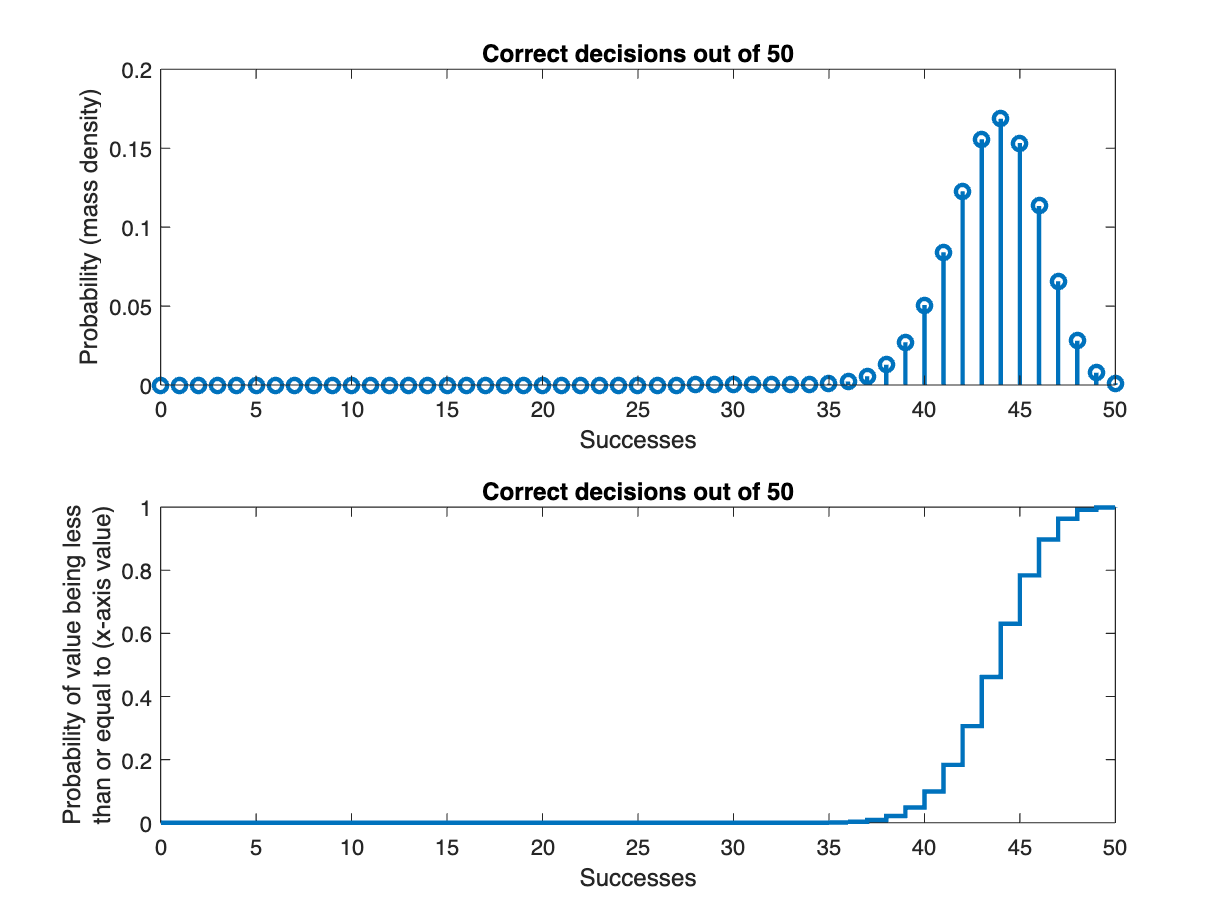

N = 50; % Number of trials
range_to_plot = 0:N; % Can't have more successes than their are trials, so stop there.

p = 0.872; %Probability of success 

mydist = makedist("Binomial","N",N,"p",p);

figure; 
subplot(2,1,1);
stem(range_to_plot,mydist.pdf(range_to_plot),'LineWidth',2); 
xlabel("Successes"); ylabel("Probability (mass density)"); title(strcat("Correct decisions out of ",num2str(N)));

subplot(2,1,2);
%stem(range_to_plot,mydist.cdf(range_to_plot),'LineWidth',2); hold on;
stairs(range_to_plot,mydist.cdf(range_to_plot),'LineWidth',2)
xlabel("Successes"); ylabel(["Probability of value being less", "than or equal to (x-axis value)"]); title(strcat("Correct decisions out of ",num2str(N)));

Use the cdf, icdf, and pdf functions below to figure out what each of these represents. Change the values and write out what each of these means.

mydist.pdf(0)

ans = 2.2935e-45

mydist.cdf(39)

ans = 0.0487

mydist.icdf(0)

ans = 0

### How many mistakes would we expect on average during a period of 4 trials with a success probability of 0.5?

2

### How many mistakes would we expect on average during a period of 4 trials with a success probability of 0.75?

1

### Imagine we were going to run this classifier in batches of 5 decisions an infinite number of times. Let's also say that our acceptable mistake threshold is 1 mistake our of 5.  Approximately what accuracy (success rate) would you need in order to meet this acceptable mistake rate 95% of the time?

Hint: I don't have a pure mathematical way to do this in mind (let me know if you figure one out). You might also want to check out the code in the next section to help think about what is happening here.

92.5% accuracy, which gives CDF = 0.0483, meaning that 0.9517 of trials will meet this threshold.

N = 5

mydist.cdf(3)

### How does this change if we only accept 1 mistake out of 50? What is the approximate accuracy needed?

We need CDF < 0.05. Guess and check shows that an accuracy of 99.3% (p = 0.993) is needed.

N = 50

mydist.cdf(48)

### How does this change if we keep the same acceptable failure rate as the first example (20%), but increase the number of decisions per batch? (aka, 10 mistakes out of 50 is acceptable)? What approximate accuracy is needed then?

An accuracy of 87.2% (p = 0.872) is needed.

N = 50

mydist.cdf(39)

### What happens to our distribution of pmfs (pdf in Matlab) with different success rates?

Change the value of N to make sure you understand what this does. What does N represent?

Then change the vector of possible_p  (the probabilities of success that we want to look at). 

#### What happens at low, medium, and high probabilities of success?  Are all the distributions the same width?

The higher probabilities of success have of course higher accuracies. The distribution widths do generally tend to be the same.

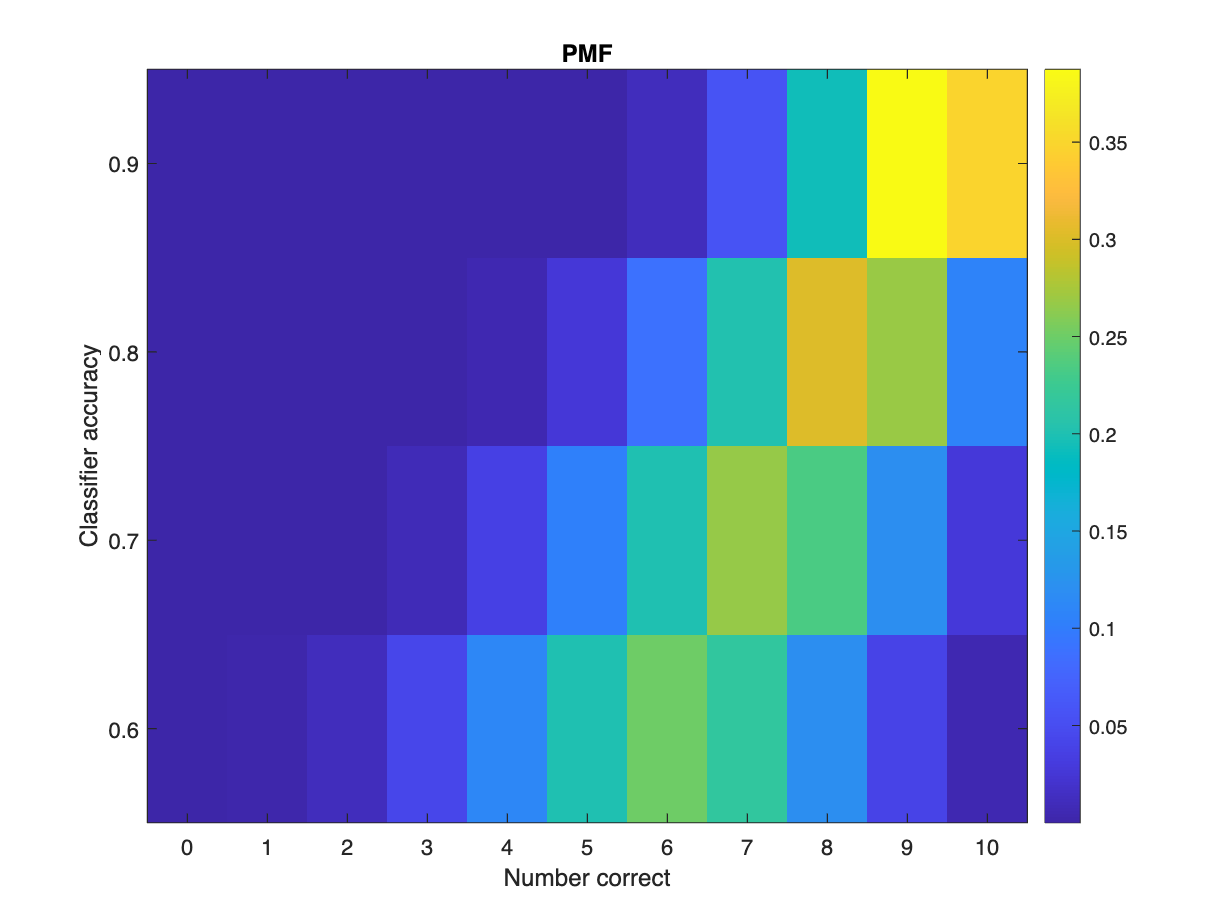

N = 10;
range_to_plot = 0:N; % Vector of number of successes to plot

possible_p = 0.6:.1:.9; % Vector of success rates (p) to look at

prob_x_successes_pdf = NaN([length(possible_p),length(range_to_plot)]); % Make an empty matrix to store results
prob_x_successes_cdf = NaN([length(possible_p),length(range_to_plot)]); % Make an empty matrix to store results

% Loop through each possible p (probability of success)
for p = 1:length(possible_p)
    % Make a temporary binomial distribution that uses the current p and N
    tempdist = makedist("Binomial","N",N,"p",possible_p(p));
    prob_x_successes_pdf(p,:) = tempdist.pdf(range_to_plot);
    prob_x_successes_cdf(p,:) = tempdist.cdf(range_to_plot);

end

% These two lines of code are just to make it so you can label the values
% on your axes without all the numbers crammed in too tight. It limits
% things to 40 labels per axis.
cbx = ceil(length(range_to_plot)/40); % Use to avoid numbers being crammed in too tight.
cby = ceil(length(possible_p)/40); %Avoid y axis being crammedin too tight

figure
imagesc(prob_x_successes_pdf); set(gca,'YDir','normal'); colorbar; title('PMF')
xlabel("Number correct"); xticks(1:cbx:length(range_to_plot)); xticklabels(range_to_plot(1:cbx:end));
ylabel("Classifier accuracy");  yticks(1:cby:length(possible_p)); yticklabels(possible_p(1:cby:end)); 

### Make the same type of plot for the cdf. What does this represent?

(Suggested ranges are N=50, p from 0.01 to .99 counting by .01.

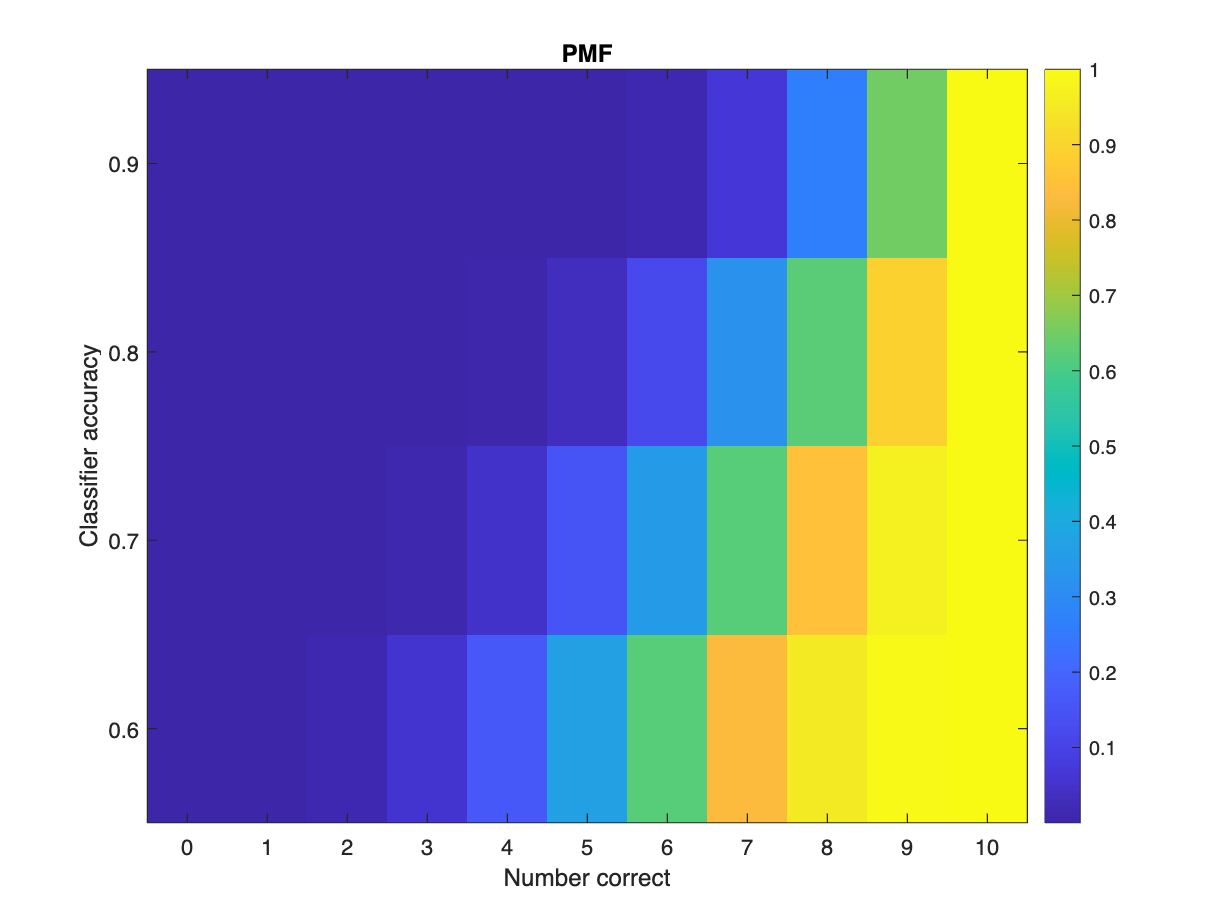

figure
imagesc(prob_x_successes_cdf); set(gca,'YDir','normal'); colorbar; title('PMF')
xlabel("Number correct"); xticks(1:cbx:length(range_to_plot)); xticklabels(range_to_plot(1:cbx:end));
ylabel("Classifier accuracy");  yticks(1:cby:length(possible_p)); yticklabels(possible_p(1:cby:end)); 

This represents the cumulative sum of the distributions for each accuracy you're looking at.